# コイン投げ

% 変数、Figure のクリア

clearvars;
clf;

表と裏の出る確率がそれぞれ $1/2$ のコインを $N$ 枚用意する．

各コインの表面には得点 $+1$ が，裏面には得点 $-1$ が割り当てられている．

$N$ 枚のコインを投げた合計得点 $E$ に対して，$\eta=E/N$ はコイン1枚あたりの平均得点と解釈できる．

$\eta$ の期待値はゼロである．

ここではコインの枚数 $N$ を変化させたときの各コインの平均値 $\eta$ を，数値シミュレーションによって調べる．

## 初期設定

コインの枚数 $N$ のリスト T を作成する．

T = 1:1:9;
for j = 1:1:7
    x = uint64(logspace(j, j+1, 20));
    T = horzcat(T, x(1:end-1));
end
T = horzcat(T, x(end))

T = 1×143 の uint64 行ベクトル
      1      2      3      4      5      6      7      8      9     10     11     13     14     16     18     21     23     26     30     34     38     43     48     55     62     70     78     89    100    113    127    144    162    183    207    234    264    298    336    379    428    483    546    616    695    785    886   1000   1129   1274


AA = [];

## コイン投げの実施

各コインの枚数 $N$ に関してコイン投げを複数回繰り返し，各試行での $\eta$ の値を取得する．

format long
for j =1:1:50
    A = zeros(size(T));
    maxT = T(end);
    tm = 1;
    cn = 0;
    sm = 0;
    avr = 0;
    chk_t = 1;
    while tm <= maxT
        cn = cn + 1.0;
        xi = 2*randi(2)-3;
        sm = sm + xi;
        if(tm == T(chk_t))
            A(chk_t) = sm / cn;
            chk_t = chk_t + 1;
        end
        tm = tm + 1;
    end
    AA = vertcat(AA, A);
end


## データ読み込みとグラフ描画

コインの枚数 $N$ が充分大きくなると，試行ごとの $\eta$ のばらつきがほとんどなくなり，平均値 $\eta$ は確率的に言って，ほぼ確実に期待値ゼロに一致することが読み取れる．

実際，$|\eta|$ の標準偏差 $\Delta \eta$ を $N$ に対して両対数グラフに表示すると，標準偏差は $\Delta \eta=N^{-0.5}$ に従って減少する様子が見て取れる．

 $\Delta \eta$ の値は$\Delta \eta=N^{-0.5}$ の近くにしか見られず，それよりも大きな値は確率的にほとんど起こらないと言える．

なお $|\eta|$ の値は $1/N$ を最小単位として離散化されているので，$|\eta|=N^{-1}$ よりも小さなデータは現れない．

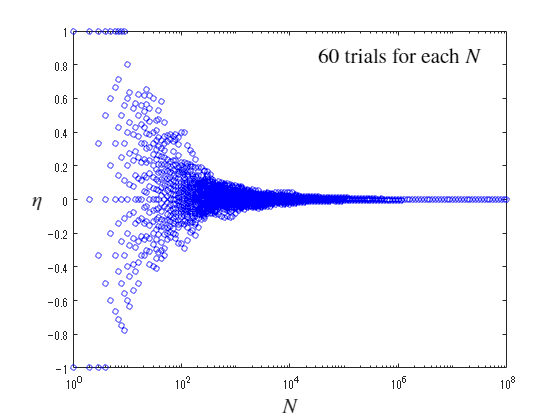

x1 = double(T);
m1 = std(AA);

semilogx(T, AA, 'ob', MarkerSize=4)
xl = xlabel('$N$', Interpreter='latex');
xl.FontSize=16;
yl = ylabel('$\eta$', Rotation=0, Interpreter='latex');
yl.FontSize=16;
%yl.Position=[0.15,0.000077552128157,0.200000047683716];

text(3e4, 0.85, '60 trials for each $N$', Interpreter='latex', FontSize=16)

%exportgraphics(gca, "Coin_Toss_eta.png")

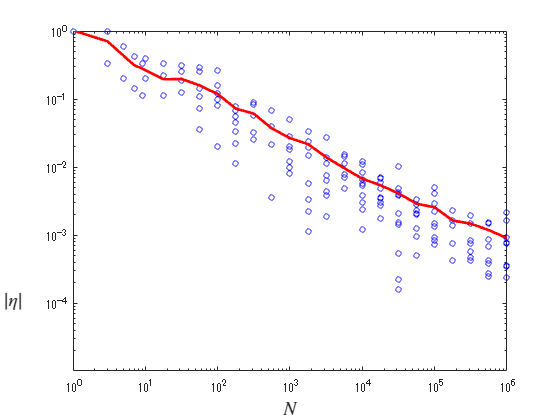


loglog(T, AA, 'ob', MarkerSize=4)
hold on
    loglog(x1, m1, '-r', LineWidth=2)
hold off
xl = xlabel('$N$', Interpreter='latex');
xl.FontSize=14;
yl = ylabel('$|\eta|$', Rotation=0, Interpreter='latex');
yl.FontSize=14;
yl.Position=[0.15,0.000077552128157,0.200000047683716];
ylim([1e-5 1])